# Dynamic Models with Latent Variables Project

### Timothée Dangleterre and Giovanni Manche

Work based on the paper A new approach to model regime switching, Chang et al. 2017, *Journal of Econometrics*

## 1. Cleaning and imports

%clear; clc; clearvars;
addpath('data');
addpath('utils');
addpath('core');
addpath('simulations');
addpath('visualisation');
rng(42);

## 2. Simulated data

### 1.1 Monte Carlo simulations

In the paper, they simulate data:

- volatility model: $\sigma_{\text{low}}$ $= 0.04, \sigma_{\text{high}} = 0.12$

- mean model: $\mu_{\text{low}} = 0.6, \mu_{\text{high}} = 3, \gamma = 0.5, \sigma = 0.8$ 

They use different values of $\rho$ $= 0, -0.1, -0.2,..., -1$, and three different couples $(\alpha, \tau)$: $(0.4, 0.5), (0.8, 0.7), (1,9.63)$. They do Monte Carlo simulations: 500 observations, 1000 simulations.

n_obs = 500;
n_simul = 1000;
rho_values = 0:-0.1:-1;

% Alpha/Tau couples
alpha_tau_pairs = [0.4, 0.5;
                   0.8, 0.7; 
                   1, 9.63];

% Base parameters
b_vol  = create_params(0, 0, 0, 0, [0.04;0.12], 0);
b_mean = create_params(0, 0, 0, [0.6;3], 0.8, 0.5);

% MC simulations
Results = run_monte_carlo_simulations(n_obs, n_simul, rho_values, ...
                                      alpha_tau_pairs, b_vol, b_mean);

Starting Monte Carlo: 3 Pairs, 11 Rho values, 1000 Sims each.
  > Processing Pair 1/3 (Alpha=0.40, Tau=0.50)...



% Visualisation
visualize_monte_carlo_check(Results, 'Mean', 1, 'visualisation/graphs/MC_simualations_mean.png');
visualize_monte_carlo_check(Results, 'Vol', 1, 'visualisation/graphs/MC_simualations_vol.png');
% Check if filter's estimates are close enough to the true values 
% Uncomment if needed but results are saved (quite long to run)
%verify_goodness_filtering(Results, [1, 240, 999], 'txt_file_results/checks_for_some_simulations.txt');

### 1.2. Bias analysis

% Uncomment if you want to run a new analysis of all MC simulations but
% very long. If no changes in the simulations, simply load the saved
% results.
% MC_Data = MC_bias(Results, 1:1000, 'simulations/bias_analysis_results');
load('MC_Raw_Data.mat');
MC_bias_graphs(MC_Data);

## 2. Real data

### 2.1. US GDP growth rate

As the authors, we use the filter for the quarterly GDP growth in the US on two subperiods: 1952-1984 and 1984-2012. We then add the new period up to 2025.  First we collect and transform the data.

US_GDP = readmatrix("data\Data_DMLV.xlsx", "Sheet", "GDP_US", "NumHeaderLines", 1);
% GDP growth (log-difference)
US_gdp_growth = diff(log(US_GDP(:,2))) * 100;
% Dates 
dates = datetime(US_GDP(2:end,1), 'ConvertFrom', 'excel');
% Plot
figure;
plot(dates, US_gdp_growth);
title('US GDP Growth Rate');
ylabel('Growth (%)');
grid on;

We then estimate the model on the subperiod before 1984. The estimated autoregressive process on the GDP growth is of order 4 and we consider a mean model.

mask = dates >= datetime(1952,1,1) & dates <= datetime(1983,12,31);
US_GDP_growth_before_1984 = US_gdp_growth(mask);
% Estimation
disp('======== US GDP GROWTH 1952-1984 ========')
output_gdp_before_1984 = run_full_analysis(US_GDP_growth_before_1984, 4, 'mean', true, true,...
    'dates', dates(mask), 'save_figs', true, 'fig_name', 'US_before_1984', ...
    'fig_format', 'png');
% We display and save the results of the estimation
save_options = struct();
save_options.save_to_file = 'txt_file_results/US_before_1984.txt';
save_options.model_name = 'US GDP Growth Rate (1952-1984)'
save_options.precision = 4;
save_options.display = true;
results_gdp_before_1984 = display_estimation_results(output_gdp_before_1984, save_options);

We now estimate the model on the subperiod 1984-2012

mask = dates >= datetime(1984,1,1) & dates <= datetime(2012,12,31);
US_GDP_growth_1984_2012 = US_gdp_growth(mask);
disp('======== US GDP GROWTH 1984-2012 ========')
output_gdp_1984_2012 = run_full_analysis(US_GDP_growth_1984_2012, 4, 'mean', true, true,...
    'dates', dates(mask), 'save_figs', true, 'fig_name', 'US_1984_2012',...
    'fig_format', 'png');

save_options.save_to_file = 'txt_file_results/US_1984_2012.txt'; 
save_options.model_name = 'US GDP Growth Rates (1984-2012)';
results_gdp_1984_2012 = display_estimation_results(output_gdp_1984_2012, save_options);

We now over the recent period (2012-2025)

mask = dates >= datetime(2012,1,1);
US_gdp_growth_recent = US_gdp_growth(mask);
disp('======== US GDP GROWTH 2012-2025 ========')
output_gdp_recent = run_full_analysis(US_gdp_growth_recent, 4, 'mean', true, true,...
    'dates', dates(mask), 'save_figs', true, 'fig_name', 'US_recent', ...
    'fig_format', 'png');
save_options.save_to_file = 'txt_file_results/US_recent.txt'; 
save_options.model_name = 'US GDP Growth Rates (2012-2025)';
results_gdp_recent = display_estimation_results(output_gdp_recent, save_options);

We propose to estimate the model over the full sample, then stopping before COVID

disp('======== US GDP GROWTH FULL SAMPLE ========')
output_gdp_all = run_full_analysis(US_gdp_growth, 4, 'mean', true, true,...
    'dates', dates, 'save_figs', true, 'fig_name', 'US_full_sample', ...
    'fig_format', 'png');
save_options.save_to_file = 'txt_file_results/US_full.txt'; 
save_options.model_name = 'US GDP Growth Rates (full sample)';
results_gdp_full_sample = display_estimation_results(output_gdp_all, save_options);

mask = dates < datetime(2020,1,1);
disp('======== US GDP GROWTH WITHOUT COVID ========')
US_gdp_growth_without_COVID = US_gdp_growth(mask);
output_gdp_without_COVID = run_full_analysis(US_gdp_growth_without_COVID, 4, 'mean', true, true,...
    'dates', dates(mask), 'save_figs', true, 'fig_name', 'US_without_COVID', ...
    'fig_format', 'png');
save_options.save_to_file = 'txt_file_results/US_without_COVID.txt'; 
save_options.model_name = 'US GDP Growth Rates (1952-2025)';
results_gdp_without_COVID = display_estimation_results(output_gdp_without_COVID, save_options);

### 2.2. VIX

We now try our volatility model on the VIX.

table_VIX = readmatrix("data\Data_DMLV.xlsx", "Sheet", "VIX", "NumHeaderLines",1);
VIX = table_VIX(:,2);
% Dates 
dates_VIX = datetime(table_VIX(:,1), 'ConvertFrom', 'excel');
% Plot
figure;
plot(dates_VIX, VIX);
title('VIX');
ylabel('Value');
grid on;
% Estimation of the volatility model
disp('======== VIX ========')
output_VIX = run_full_analysis(VIX, 0, 'volatility', true, true,...
    'dates', dates_VIX, 'save_figs', true, 'fig_name', 'VIX', ...
    'fig_format', 'png');
save_options.save_to_file = 'txt_file_results/VIX.txt';
save_options.model_name = 'VIX'
save_options.precision = 4;
save_options.display = true;
save_options.model_type = 'volatility';
results_VIX = display_estimation_results(output_VIX, save_options);

### 2.3. Overnight rate

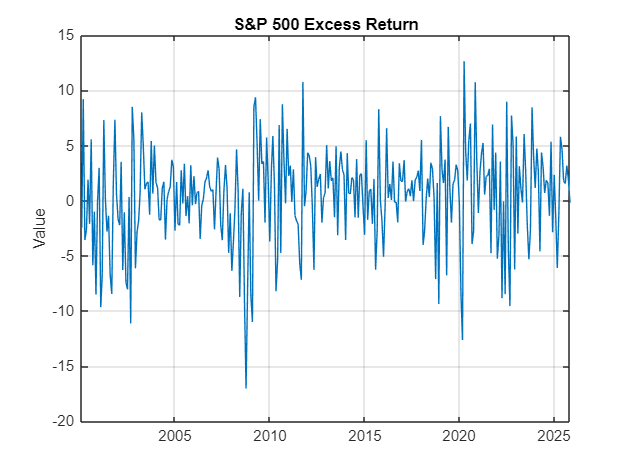

table_EONIA = readmatrix("data\Data_DMLV.xlsx", "Sheet", "EONIA", "NumHeaderLines",1);
EONIA = table_EONIA(:,2);
% Dates 
dates_EONIA = datetime(table_EONIA(:,1), 'ConvertFrom', 'excel');
% Plot
figure;
plot(dates_EONIA, EONIA);
title('EONIA index');
ylabel('Value');
grid on;

% Estimation of the volatility model
disp('======== EONIA ========')

======== Excess returns ========



STARTING ANALYSIS: VOLATILITY Model (k=0)
1. Estimating Endogenous Model (Free Rho)...
Starting Optimization for VOLATILITY model...
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           7    8.824538e+02     0.000e+00     1.000e+00     0.000e+00     1.136e+01  
    1          21    8.814370e+02     0.000e+00     8.235e-02     9.789e-01     1.342e+01  
    2          33    8.802854e+02     0.000e+00     1.681e-01     1.002e+00     2.966e+01  
    3          43    8.797480e+02     0.000e+00     3.430e-01     1.344e+00     1.376e+01  
    4          50    8.714943e+02     0.000e+00     1.000e+00     1.982e+00     1.589e+02  
    5          68    8.713188e+02     0.000e+00     1.977e-02     9.076e-02     1.685e+01  
    6          84    8.712728e+02     0.000e+00   

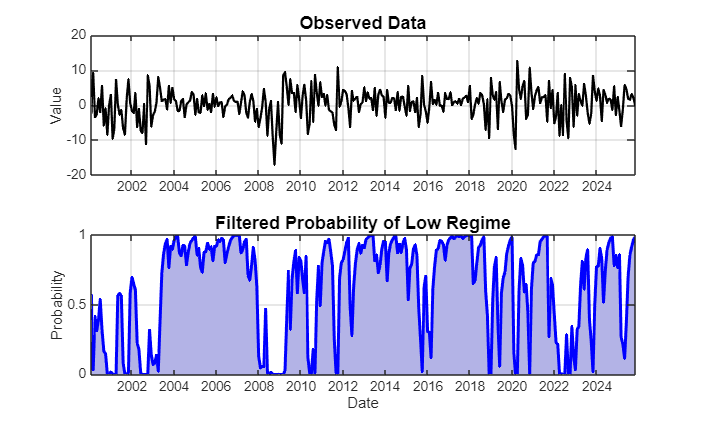

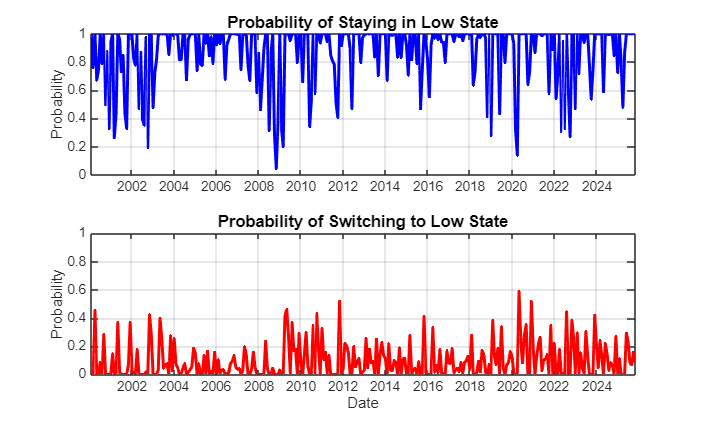

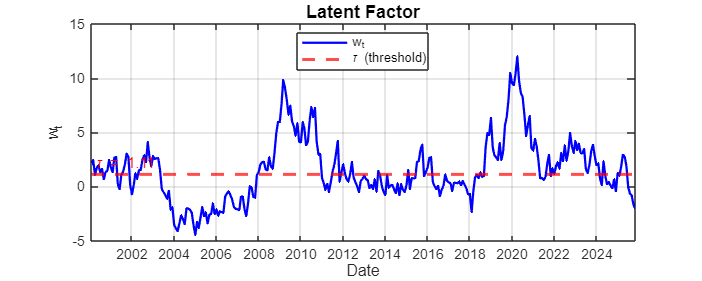

output_EONIA = run_full_analysis(EONIA, 0, 'volatility', true, true,...
    'dates', dates_EONIA, 'save_figs', true, 'fig_name', 'EONIA', ...
    'fig_format', 'png');

save_options.save_to_file = 'txt_file_results/EONIA.txt';
save_options.model_name = 'EONIA';

save_options = struct with fields:
    save_to_file: 'txt_file_results/excess_returns.txt'
      model_name: 'excess_returns'
       precision: 4
         display: 1


save_options.precision = 4;
save_options.display = true;
results_EONIA = display_estimation_results(output_EONIA, save_options);

### 2.4) Excess returns of the S&P 500

table_excess = readmatrix("data\Data_DMLV.xlsx", "Sheet", "Excess_return", "NumHeaderLines",1);


 excess_returns
----------------------------------------------------------------------
 ENDOGENOUS MODEL (Chang et al.)
----------------------------------------------------------------------
Parameter            | Estimate     | Std.Err      | t-Stat    
----------------------------------------------------------------------
Mu (Constant)        |       0.7947 |       0.1977 |       4.02 ***
Sigma (Low/Normal)   |       2.6879 |       0.9070 |       2.96 ***
Sigma (High/Crisis)  |       6.1902 |       1.4136 |       4.38 ***
Alpha (Latent)       |       0.9438 |       0.1391 |       6.79 ***
Tau (Threshold)      |       1.1118 |       1.0845 |       1.03 
Rho (Endogeneity)    |      -0.9900 |       1.0353 |      -0.96 
----------------------------------------------------------------------
Log-Likelihood : -866.3219
-------------------------------

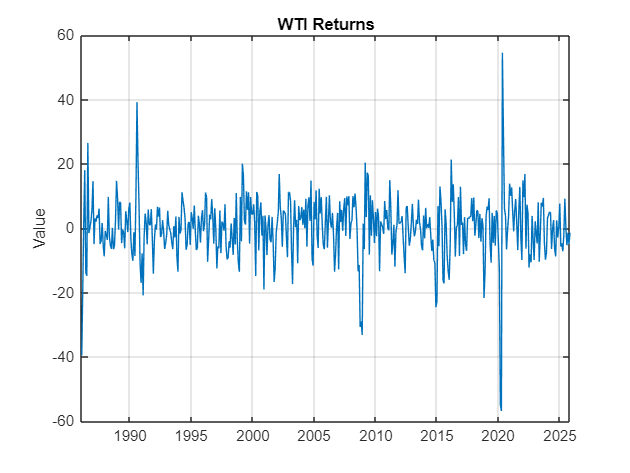

excess_returns = table_excess(:,2);
% Dates 
dates_excess = datetime(table_excess(:,1), 'ConvertFrom', 'excel');
% Plot
figure;
plot(dates_excess, excess_returns);
title('S&P 500 Excess Return');
ylabel('Value');
grid on;
% Estimation of the volatility model
disp('======== Excess returns ========')
output_excess = run_full_analysis(excess_returns, 0, 'volatility', true, true,...
    'dates', dates_excess, 'save_figs', true, 'fig_name', 'excess_returns', ...

    'fig_format', 'png');
save_options.save_to_file = 'txt_file_results/excess_returns.txt';
save_options.model_name = 'excess_returns'
save_options.precision = 4;
save_options.display = true;
save_options.model_type = 'volatility';
results_excess = display_estimation_results(output_excess, save_options);

### 2.5) WTI

% Vol
table_WTI = readmatrix("data\Data_DMLV.xlsx", "Sheet", "WTI", "NumHeaderLines",1);
WTI_returns = diff(log(table_WTI(:,2))) * 100;
% Dates 
dates_WTI = datetime(table_WTI(2:end,1), 'ConvertFrom', 'excel');
% Plot
figure;
plot(dates_WTI, WTI_returns);
title('WTI Returns');
ylabel('Value');
grid on;

% For the mean model, we will use an AR(p) with p given by the standard
% information criterion for a standard (linear) AR
T = length(WTI_returns);
% We cap the number of lags at 6
pmax = 6;
% AIC / BIC
AIC = zeros(pmax, 1);
BIC = zeros(pmax, 1);
% LOOP ON THE NUMBERS OF LAG
for p = 1:pmax
    % OLS
    X = ones(T - p,1);
    Y = WTI_returns((1 + p):end);
    for i = 1:p
        X(:, end+1) = WTI_returns(p-i+1:T-i);
    end
    beta = inv(X'*X) * (X'*Y);
    e = Y - X*beta;
    vare = (e'*e)/(length(e)-1);

    % Number of variables in the model (intercept included)

    "Le critère d'information BIC préconise"    "2"    "retards."



p_opt_bic = 2

    "Le critère d'information AIC préconise"    "6"    "retards."



    K = p + 1;
    % Compute AIC / BIC

======== WTI volatility ========



STARTING ANALYSIS: VOLATILITY Model (k=0)
1. Estimating Endogenous Model (Free Rho)...
Starting Optimization for VOLATILITY model...
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           7    1.726187e+03     0.000e+00     1.000e+00     0.000e+00     3.057e+01  
    1          21    1.717878e+03     0.000e+00     8.235e-02     2.034e+00     6.470e+01  
    2          33    1.717221e+03     0.000e+00     1.681e-01     3.632e+00     3.099e+01  
    3          41    1.709376e+03     0.000e+00     7.000e-01     2.750e+00     3.699e+01  
    4          49    1.699045e+03     0.000e+00     7.000e-01     5.239e+00     8.991e+01  
    5          56    1.693772e+03     0.000e+00     1.000e+00     3.188e+00     6.369e+01  
    6          66    1.691000e+03     0.000e+00   

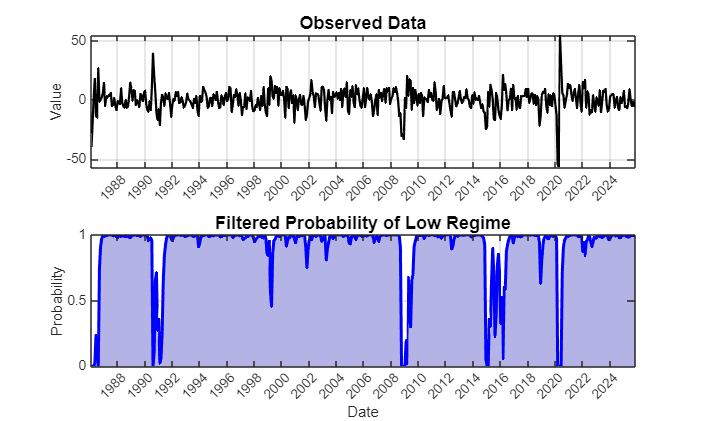

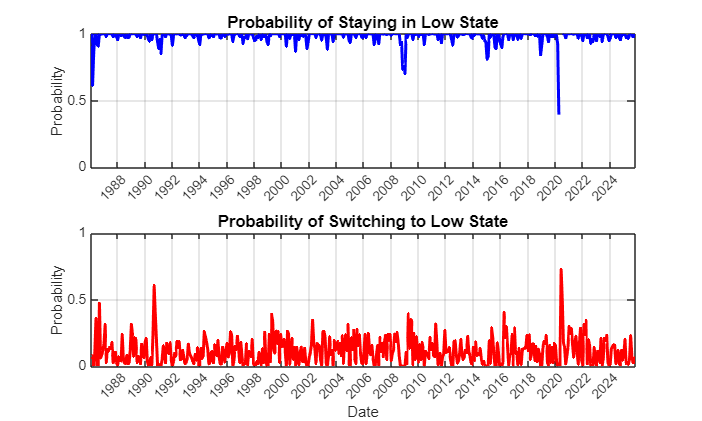

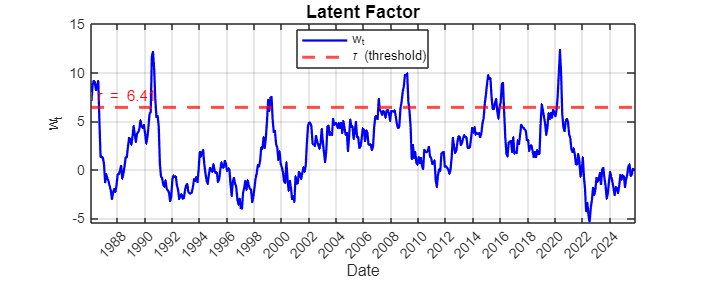

    AIC(p) = T * log(vare) + 2*K;
    BIC(p) = T * log(vare) + K*log(T);
end

 
% Print optimal number of lags with AIC / BIC

save_options = struct with fields:
    save_to_file: 'txt_file_results/WTI_volatility.txt'
      model_name: 'WTI_volatility'
       precision: 4
         display: 1
      model_type: 'volatility'


for p=1:pmax
    if(AIC(p) == min(AIC))
        disp(["AIC criterion gives ", p, " optimal lags."]);
        p_opt_aic = p;


 WTI_volatility
----------------------------------------------------------------------
 ENDOGENOUS MODEL (Chang et al.)
----------------------------------------------------------------------
Parameter            | Estimate     | Std.Err      | t-Stat    
----------------------------------------------------------------------
Mu (Constant)        |       0.4932 |       0.3434 |       1.44 
Sigma (Low/Normal)   |       6.9337 |       0.3189 |      21.74 ***
Sigma (High/Crisis)  |      23.0397 |       4.9375 |       4.67 ***
Alpha (Latent)       |       0.9720 |       0.0317 |      30.68 ***
Tau (Threshold)      |       6.4088 |       3.6639 |       1.75 *
Rho (Endogeneity)    |      -0.9779 |       0.0987 |      -9.91 ***
----------------------------------------------------------------------
Log-Likelihood : -1677.1624
-----------------------------

    end


======== WTI mean ========



STARTING ANALYSIS: MEAN Model (k=2)
1. Estimating Endogenous Model (Free Rho)...
Starting Optimization for MEAN model...
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           9    1.742036e+03     0.000e+00     1.000e+00     0.000e+00     5.011e+01  
    1          33    1.739515e+03     0.000e+00     4.748e-03     2.426e-01     3.787e+01  
    2          56    1.739426e+03     0.000e+00     6.782e-03     1.855e-01     3.452e+01  
    3          70    1.733161e+03     0.000e+00     1.681e-01     1.821e+00     3.277e+01  
    4          84    1.732780e+03     0.000e+00     1.681e-01     1.008e+00     2.919e+01  
    5          96    1.732187e+03     0.000e+00     3.430e-01     2.177e+00     5.885e+01  
    6         106    1.726887e+03     0.000e+00     7.000e-01 

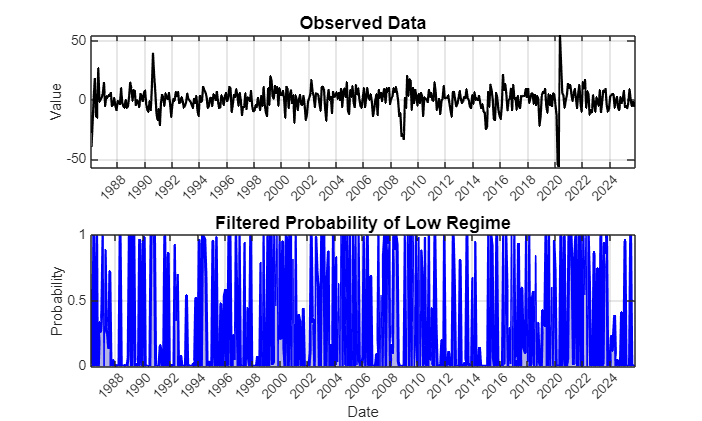

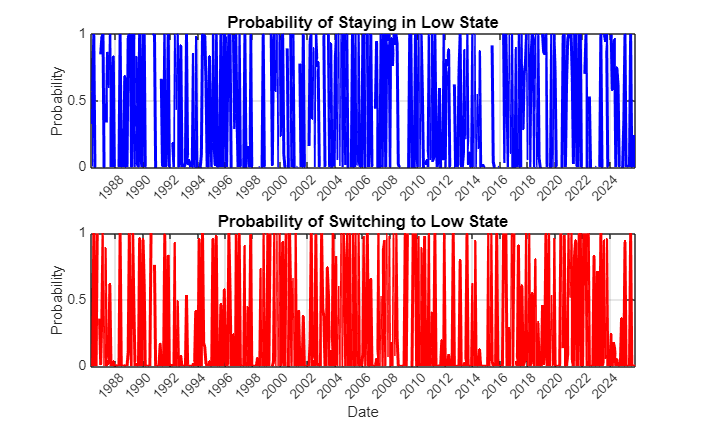

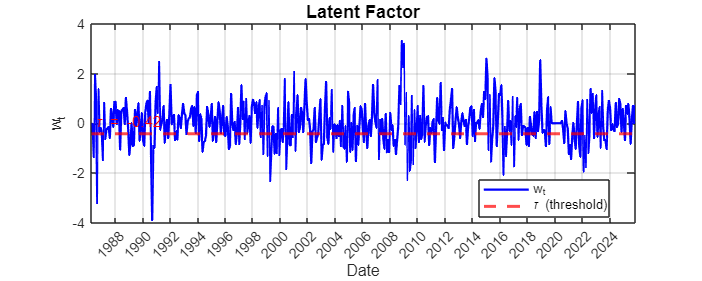

    if(BIC(p) == min(BIC))
        disp(["BIC criterion gives ", p, " optimal lags."]);
        p_opt_bic = p

    end
end

save_options = struct with fields:
    save_to_file: 'txt_file_results/WTI_mean.txt'
      model_name: 'WTI_mean'
       precision: 4
         display: 1
      model_type: 'volatility'


The AIC criterion recommands using 6 lags, but the BIC criterion, known to be more parsimonious, recommands 2 lags. That's the number for which we settle for the mean model.

disp('======== WTI volatility ========')
output_WTI_vol = run_full_analysis(WTI_returns, 0, 'volatility', true, true,...
    'dates', dates_WTI, 'save_figs', true, 'fig_name', 'WTI_vol', ...
    'fig_format', 'png');


 WTI_mean
----------------------------------------------------------------------
 ENDOGENOUS MODEL (Chang et al.)
----------------------------------------------------------------------
Parameter            | Estimate     | Std.Err      | t-Stat    
----------------------------------------------------------------------
Mu (Recession)       |      -1.9309 |       3.5052 |      -0.55 
Mu (Expansion)       |       1.3644 |       2.4404 |       0.56 
Sigma (Constant)     |       8.9449 |       0.3109 |      28.77 ***
Alpha (Latent)       |       0.0570 |       1.2981 |       0.04 
Tau (Threshold)      |      -0.4240 |       0.3592 |      -1.18 
Rho (Endogeneity)    |      -0.9900 |       0.3982 |      -2.49 **
Gamma (AR1)          |       0.3998 |       0.1944 |       2.06 **
Gamma (AR2)          |      -0.1967 |       0.0425 |      -4.63 ***
-------

save_options.save_to_file = 'txt_file_results/WTI_volatility.txt';
save_options.model_name = 'WTI_volatility'
save_options.precision = 4;
save_options.display = true;
save_options.model_type = 'volatility';
results_WTI_vol = display_estimation_results(output_WTI_vol, save_options);

disp('======== WTI mean ========')
output_WTI_mean = run_full_analysis(WTI_returns, 2, 'mean', true, true,...
    'dates', dates_WTI, 'save_figs', true, 'fig_name', 'WTI_mean', ...
    'fig_format', 'png');
save_options.save_to_file = 'txt_file_results/WTI_mean.txt';
save_options.model_name = 'WTI_mean'
save_options.precision = 4;
save_options.display = true;
save_options.model_type = 'mean';
results_WTI_mean = display_estimation_results(output_WTI_mean, save_options);